## **COOPERATIVE ROBOTS- project 04**

**GROUP 8: Aldovini, Elaamery, Pesavento **

clear all;
close all;
warning('off');

## ROBOT dynamics

% constinuous system parameters
mass = 1;
inertia = 1;
n = 4;
m = 2;
A = [0, 0, 1, 0; 0, 0, 0, 1; 0, 0, 0, 0; 0, 0, 0, 0]; % state matrix
B = [0, 0; 0, 0; 1/mass, 0; 0, 1/mass]; % consider inertia
C = eye(n);
D = zeros([n, m]); 

% continuous-time system
plantc = ss(A,B,C,D);
% discrete-time system
Ts = 0.1; % sample time
plant = c2d(plantc, Ts, 'zoh'); % exact discretization

% initial state/position
x0 = [10; 14; 0; 0];

## Algorithm parameters

% proximity parameter to the goal position (tolleranza per il goal)
delta = 0.1;

% COMMON PARAMETERS 
% weight for intermediate states
Q_weight = 1;
% weight for inputs
R_weight = 0.9;
% weight for last state only
P_weight = 1;
% predictive horizon
N = 20;
P = [1 0 0 0; 0 1 0 0]; % Px nel paper
%Policy params
policy_halt = true;
k_loose_grip = 3;   % orizzonte di predizione con recovery policy
eps_loose_grip = 0.01;

% LEADER PARAMETERS
leaderParams.Q = Q_weight*eye(n);       
leaderParams.R = R_weight*eye(m);
leaderParams.P = P_weight*eye(n);
% limit on leader acceleration, both x and y axes
leaderParams.u_lim = 1; 
% limit on leader velocity, both x and y axes
leaderParams.v_lim = 1; 
leaderParams.pos_color = "red";
leaderParams.pred_color = "magenta";
leaderParams.constraint_color = "yellow";
leaderParams.show_predictions = true;
leaderParams.show_constraints = true;
leaderParams.keep_predictions = false;
% initial shape of leader
th = 0:0.3:2*pi;
leaderParams.initRobotShape = 0.32*[cos(th); sin(th)];  % inizialmente forma circolare (set di punti del leader)
leaderParams.robotShape = leaderParams.initRobotShape;
[~ , leaderParams.L] = size(leaderParams.robotShape);

% FOLLOWER PARAMETERS
% relative distance from leader to follower to have (between the center of
% mass of the robots)
followerParams.d_FL = 1;
% relative cost for distance errors
followerParams.C = 5000;
% limit on follower acceleration, to be higher than leader
followerParams.u_lim = 2; 
% limit on follower velocity, to be higher than leader
followerParams.v_lim = 1.5;
% exponential decay of tracking quality over the prediction
followerParams.beta = 0.95;
followerParams.pos_color = "blue";
followerParams.pred_color = "cyan";
followerParams.constraint_color = "green";
followerParams.show_predictions = true;
followerParams.show_constraints = false;
followerParams.keep_predictions = false;
followerParams.initRobotShape = (0.2*[-1, 1, 1, -1; -1, -1, 1, 1]...
                            +followerParams.d_FL*[-1,0, 0, -1; 0,0,0,0]);
followerParams.robotShape =followerParams.initRobotShape;
[~ , followerParams.L] = size(followerParams.robotShape);

## Obstacle parameters

% type of environment for papers
[x0, obstacles] = setupEnvironment("valzer");
[~, M] = size(obstacles);
% can be overrridden, eventually set value for x0, and cell array obstacles

## Precompiled stuff for optimization

Not really that effective unless we compile the whole script

% precompiled follower elements (GENERAZIONE MATRICI PER LE FUNZIONI COSTO)
followerParams.precompiledElements.Sd_bar = getSdbar(plant.A, plant.B, N);
followerParams.precompiledElements.Td_bar = getTdbar(plant.A, N);
followerParams.precompiledElements.S_bar = getSbar(plant.A, plant.B, N);
followerParams.precompiledElements.T_bar = getTbar(plant.A, N);
followerParams.precompiledElements.H1 = ...
    followerParams.precompiledElements.S_bar'*followerParams.precompiledElements.S_bar;
followerParams.precompiledElements.beta_vec = followerParams.beta .^ (0:(N-1))';
followerParams.precompiledElements.N = N;
followerParams.precompiledElements.d = followerParams.d_FL;
followerParams.precompiledElements.C = followerParams.C;
followerParams.precompiledElements.L = size(followerParams.robotShape) * [0;1];
followerParams.precompiledElements.M = length(obstacles);
followerParams.precompiledElements.vertexes = followerParams.robotShape;
followerParams.precompiledElements.P = P;
followerParams.precompiledElements.P_bar = kron(eye(N), followerParams.precompiledElements.P);

leaderParams.precompiledElements.P = P;
leaderParams.precompiledElements.P_bar = kron(eye(N), followerParams.precompiledElements.P);
leaderParams.precompiledElements.Sd_bar = followerParams.precompiledElements.Sd_bar;
leaderParams.precompiledElements.Td_bar = followerParams.precompiledElements.Td_bar;
leaderParams.precompiledElements.S_bar = followerParams.precompiledElements.S_bar;
leaderParams.precompiledElements.T_bar = followerParams.precompiledElements.T_bar;

## MPC implementation 

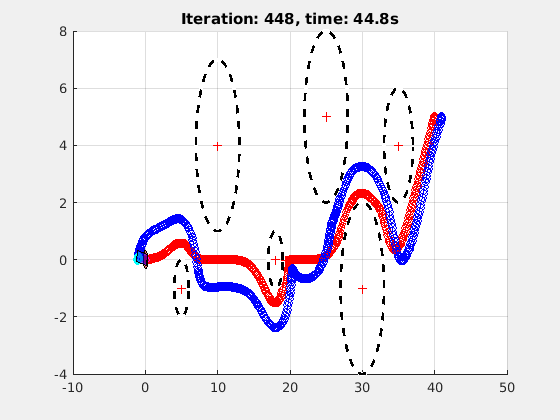

% variable meaning
% x_l, x_f = actual states of leader, follower
% X_L, X_L_stacked = preferred path by leader, 4xN and 4*Nx1 the stacked
% real_d = actual distance between robots

% goal state flag 
goal_reached = false;
i = 1;

% initialization leader and follower STATES
x_l(:,i) = x0;
x_f(:,i) = x0 + [followerParams.d_FL; 0; 0; 0]; % at initial condition we have horizontal disposition with d_FL distance
% initial guesses for optimal inputs
U_l_old = zeros([2*N,1]);
U_f_old = zeros([2*N,1]);

figure; 
set(gcf,'Visible','on'); hold on; grid on;
sp = SystemPlotter(leaderParams, followerParams, x_l(:,1), x_f(:, 1), N, obstacles);
% sp = SystemPlotter(leaderParams, followerParams, x_l(:,1), [], N, obstacles);
tit = title("Iteration 1, time: 0s");

tic
while (~goal_reached) %&& (i < 500) % terminal condition: goal reach or maximum iteration
    
    % obtain the next state, the planned path, the identified qis and solver error for leader
    [x_l(:,i+1), X_L, qi_leader, ~, U_l_old] = leaderMPCandUpdate(plant, x_l(:,i), N, leaderParams, obstacles, U_l_old);
    
    % stack the planned path to supply to the follower, and have it do mpc
    X_L_stacked = reshape(X_L, [4*N, 1]);
    %LINEAR follower constraints:
    [x_f(:,i+1), X_F, qi_follower, ~, U_f_old] = followerMPCandUpdate(...
        plant, X_L_stacked, x_f(:,i), N, followerParams, obstacles, U_f_old);
%     %NON-LINEAR follower constraints:
%     [x_f(:,i+1), X_F, qi_follower, ~, U_f_old] = followerMPCandUpdateNC(...
%     plant, X_L_stacked, x_f(:,i), N, followerParams, obstacles, U_f_old);

    if policy_halt 
        % check if trajectory does not loose the load
        formation_error_allt = abs(vecnorm(P*(X_L-X_F))-followerParams.d_FL);
        if any(formation_error_allt(1:k_loose_grip) > eps_loose_grip)
            % obtain the next state, the planned path, the identified qis and solver error for leader
            [x_l(:,i+1), X_L, qi_leader, ~, U_l_old] = leaderMPCandUpdateHalt(plant, x_l(:,i), N, leaderParams, obstacles, zeros([2*N,1]));
            
            % stack the planned path to supply to the follower, and have it do mpc
            X_L_stacked = reshape(X_L, [4*N, 1]);
            %LINEAR follower constraints:
            [x_f(:,i+1), X_F, qi_follower, ~, U_f_old] = followerMPCandUpdate(...
                plant, X_L_stacked, x_f(:,i), N, followerParams, obstacles, zeros([2*N,1]));
%           %NON-LINEAR follower constraints:
%           [x_f(:,i+1), X_F, qi_follower, ~, U_f_old] = followerMPCandUpdateNC(...
%               plant, X_L_stacked, x_f(:,i), N, followerParams, obstacles, U_f_old);
        end
    end
    % get the instantaneous rotation of load and apply to load and leader
    fl_diff = x_f(:,i+1) - x_l(:,i+1);
    loadTheta = atan2(fl_diff(2), fl_diff(1));
    
    leaderParams.robotShape = Rmat(loadTheta)*leaderParams.initRobotShape;
    followerParams.robotShape = Rmat(loadTheta)*followerParams.initRobotShape;
    
    % check if goal was reached up to desired precision
    if norm(x_l(:,i+1)) < delta
        goal_reached = true;
    end
    
     % distance between the 2 robots
     real_d(i) = norm(x_l(1:2,i) - x_f(1:2,i));
   
    % do the plotting
    sp.updateLeaderPath(x_l(:,i), X_L);
    sp.updateLoadPos(x_l(:,i), x_f(:,i), loadTheta);
    sp.updateObstacles(obstacles, length(obstacles));
    sp.updateFollowerPath(x_f(:,i), X_F);
    tit.String = "Iteration: "+num2str(i)+", time: "+num2str(i*Ts)+"s";
    sp.redraw();
    
    %Obstacle dynamics 
    obstacles = obstacles_dynamics(obstacles, Ts);  
    
    % update iteration
    i = i+1;
    
end

execution_time = toc % [s]

execution_time = 146.9013

## Result plot

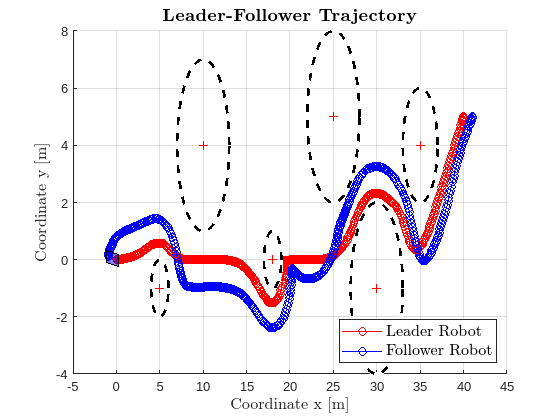

time = 0:Ts:Ts*(i-1);
%Trajectory plot
figure;  hold on; grid on;
plot( x_l(1,:), x_l(2,:), "-o","Color", "red");
plot( x_f(1,:), x_f(2,:), "-o","Color", "blue")
plotObstacles(obstacles);
plot(...
    polyshape(x_f(1,end)+followerParams.robotShape(1,:),...
              x_f(2,end)+followerParams.robotShape(2,:)),...
    'FaceColor',followerParams.pos_color,'FaceAlpha',0.5);
title("\textbf{Leader-Follower Trajectory}","Interpreter","latex", "FontSize", 14)
xlabel("Coordinate x [m]","Interpreter","latex", "FontSize", 12)
ylabel("Coordinate y [m]","Interpreter","latex", "FontSize", 12)
legend("Leader Robot","Follower Robot","Location","southeast","Interpreter","latex", "FontSize", 12)

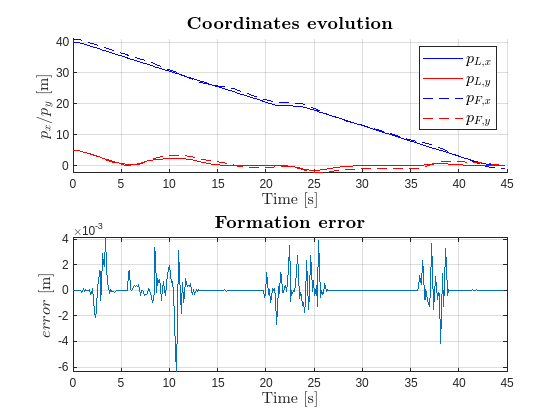


%Coordinates evolution and formation error plot
figure; 
subplot(2,1,1)
hold on; grid on;
plot(time, x_l(1,:), "-b", time, x_l(2,:), "-r");
plot(time, x_f(1,:), "--b", time, x_f(2,:), "--r");
xlabel("Time [s]", "Interpreter","latex","FontSize", 12)
ylabel("$p_x$/$p_y$ [m]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Coordinates evolution}", "Interpreter","latex", "FontSize", 14)
legend("$p_{L,x}$","$p_{L,y}$","$p_{F,x}$","$p_{F,y}$","Interpreter","latex", "FontSize", 12)

subplot(2,1,2)
plot(time(1:end-1),real_d - followerParams.d_FL);
grid on;
xlabel("Time [s]", "Interpreter","latex", "FontSize", 12)
ylabel("$error$ [m]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Formation error}", "Interpreter","latex", "FontSize", 14)

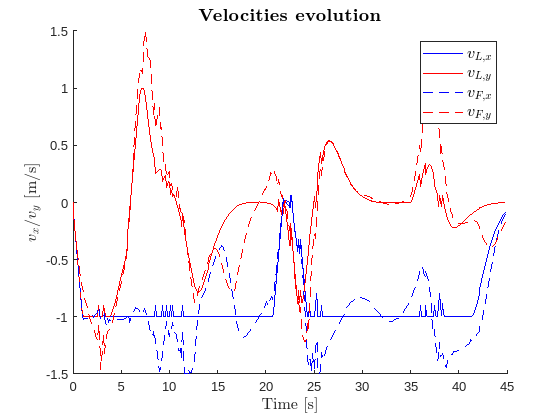


figure;
hold on;
plot(time, x_l(3,:), "-b", time, x_l(4,:), "-r");
plot(time, x_f(3,:), "--b", time, x_f(4,:), "--r");
xlabel("Time [s]", "Interpreter","latex","FontSize", 12)
ylabel("$v_x$/$v_y$ [m/s]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Velocities evolution}", "Interpreter","latex", "FontSize", 14)
legend("$v_{L,x}$","$v_{L,y}$","$v_{F,x}$","$v_{F,y}$","Interpreter","latex", "FontSize", 12)

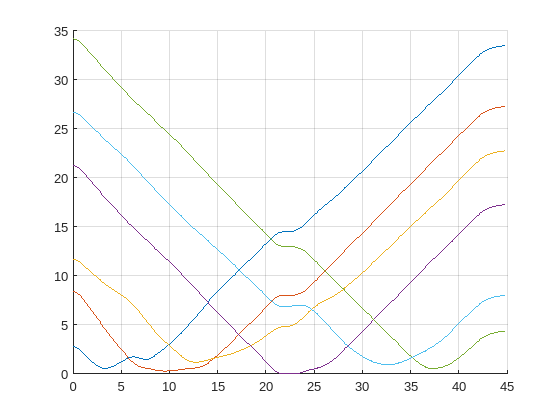

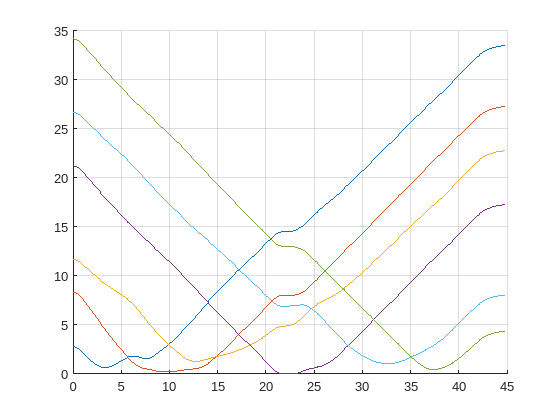

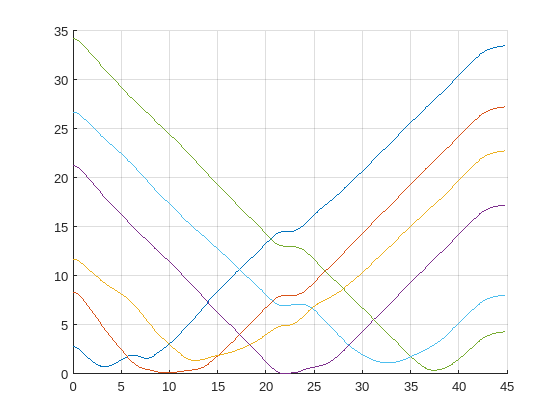

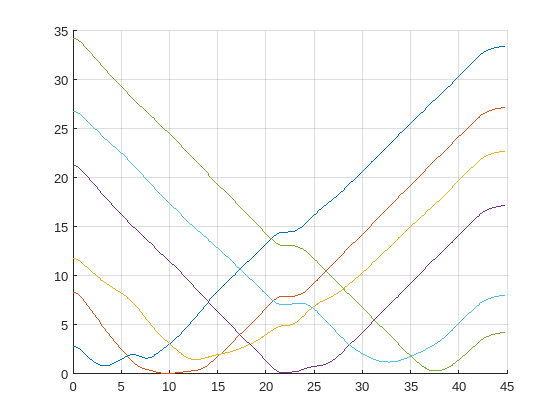

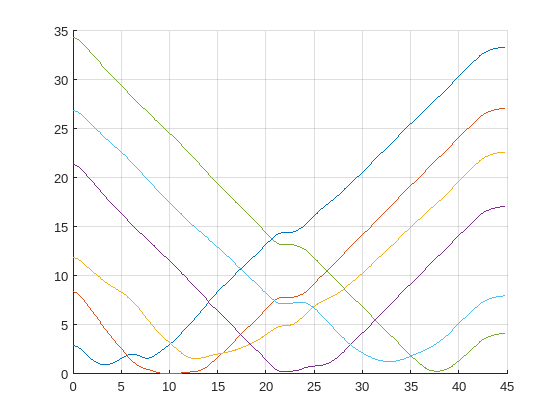

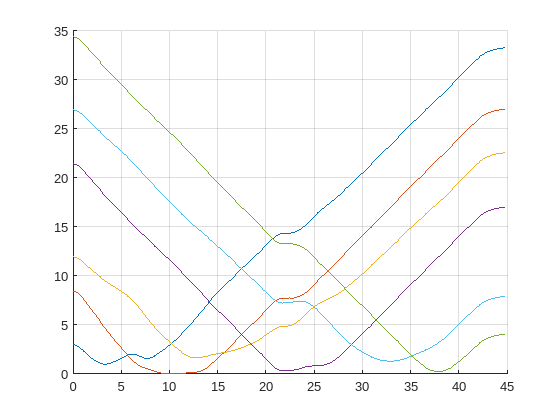

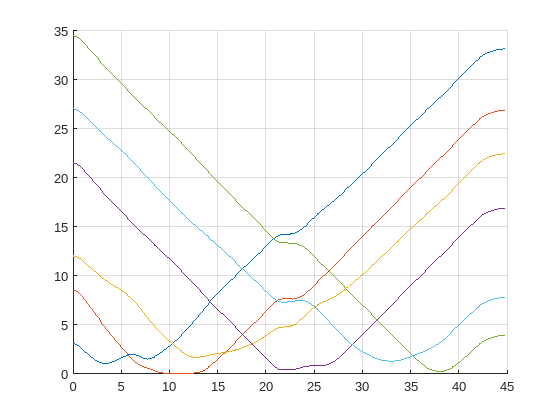

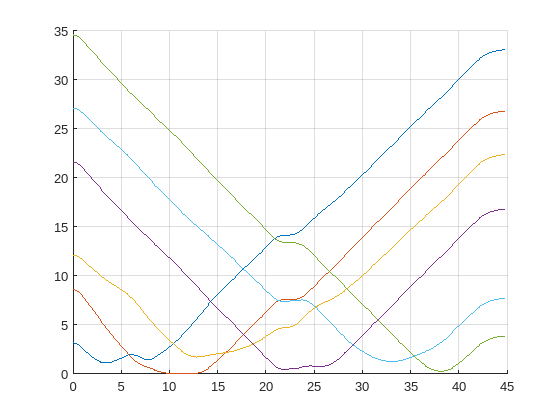

% PLOTTING DEI VERTICI RISPETTO AGLI OSTACOLI
for j=1:leaderParams.L
    dist_l{j} = zeros(length(time), M);
end
for o=1:M
    for j=1:leaderParams.L
        for t=1:length(time)
            dist_l{j}(t,o)= norm((x_l(1:2, t)+leaderParams.robotShape(:, j)) - obstacles{o}.center) - obstacles{o}.radius;
        end
    end
end
for j=1:leaderParams.L
    figure;
    hold on;
    grid on;
    for o=1:M
        plot(time, dist_l{j}(:,o));
    end
end

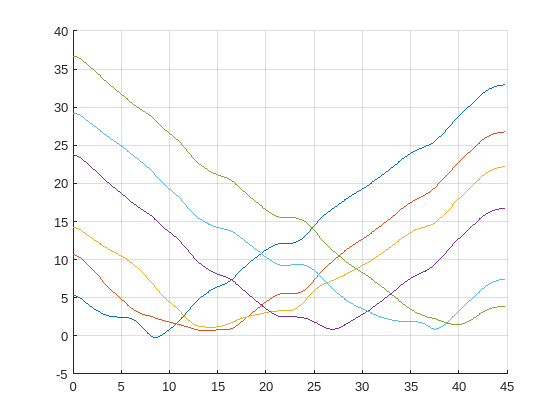

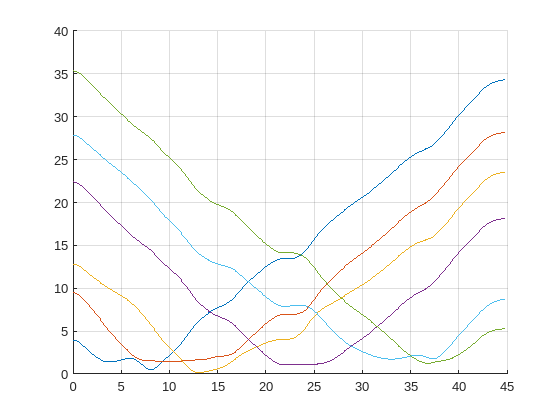

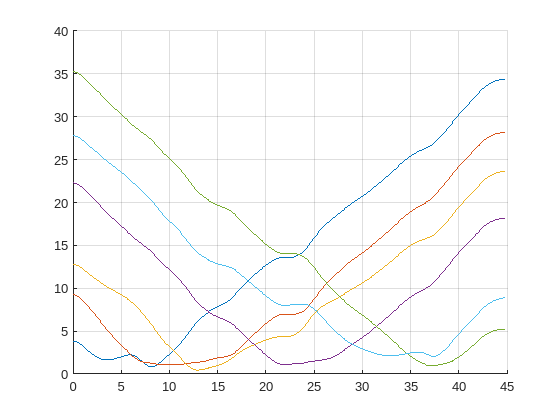

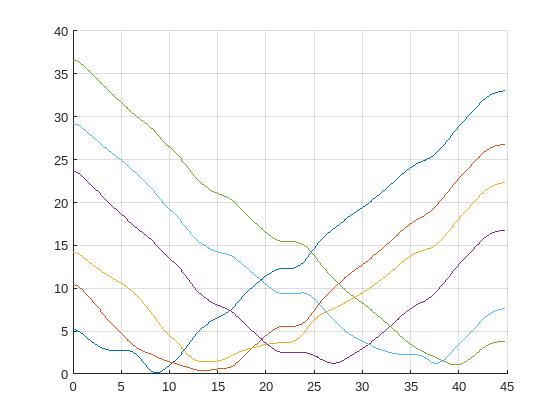


for j=1:followerParams.L
    dist_f{j} = zeros(length(time), M);
end
for o=1:M
    for j=1:followerParams.L
        for t=1:length(time)
            dist_f{j}(t,o)= norm((x_f(1:2, t)+followerParams.robotShape(:, j)) - obstacles{o}.center) - obstacles{o}.radius;
        end
    end
end
for j=1:followerParams.L
    figure;
    hold on;
    grid on;
    for o=1:M
        plot(time, dist_f{j}(:,o));
    end
end